# **泰坦尼克号生存预测**

首先修改工作文件夹到有数据的那个文件夹

clear; clc
cd 'C:\Users\sxjmqf\Desktop\机器学习进阶课程\3.泰坦尼克号生存预测'

导入数据，偷懒的方法就是使用MATLAB的导入数据功能，然后自动生成脚本

这是我设置的数据类型：

这里的数据类型很有讲究，我们常用的是**数值**和**分类**两种数据类型。

数值型比较好理解，我们来看看分类型:

(1)有些分类变量很明显，例如性别：男和女  读取进来后MATLAB会自动帮我们识别为分类型。

(2)有些分类变量是用数值表示的，例如填问卷用1234分别表示四个选项，这时候MATLAB读进来的时候可能给我们默认是数值型，你得改成分类型。

**分类型和文本型的区别是什么？**

通常来说分类型中包含的类别比较少，而文本型中每个样本的区别都很大。

通常我们在模型中不引入文本型的变量，除非你自己提取文本型中有用的信息来生成新的指标。

filename = 'data.csv';
delimiter = ',';
startRow = 2;
formatSpec = '%f%C%C%q%C%f%f%f%q%f%C%C%[^\n\r]';
fileID = fopen(filename,'r');
dataArray = textscan(fileID, formatSpec, 'Delimiter', delimiter, 'TextType', 'string', 'EmptyValue', NaN, 'HeaderLines' ,startRow-1, 'ReturnOnError', false, 'EndOfLine', '\r\n');
fclose(fileID);
data = table(dataArray{1:end-1}, 'VariableNames', {'PassengerId','Survived','Pclass','Name','Sex','Age','SibSp','Parch','Ticket','Fare','Cabin','Embarked'});
%% 清除临时变量
clearvars filename delimiter startRow formatSpec fileID dataArray ans;

Survived:0代表死亡，1代表存活

Pclass:乘客所持票类，有三种值(1,2,3)

Name:乘客姓名

Sex:乘客性别

Age:乘客年龄(有缺失)

SibSp:乘客兄弟姐妹/配偶的个数(整数值)

Parch:乘客父母/孩子的个数(整数值)

Ticket:票号(字符串)

Fare:乘客所持票的价格(浮点数，0-500不等)

Cabin:乘客所在船舱(有缺失)

Embarked:乘客登船港口:S、C、Q(有缺失)

最开始的PassengerId表示乘客的编号，可以忽略。

MATLAB表格的用法：

[https://ww2.mathworks.cn/help/matlab/tables.html](https://ww2.mathworks.cn/help/matlab/tables.html)

head(data,10)  % 查看表的前10行
summary(data)  % 返回表中各个指标的信息
N = height(data)  % 表的高度，即样本量
data.Properties.VariableNames  % 变量名称

## 一般我们先不用考虑数据异常值的情况，除非遇到了下面几种情况：

（1）题目明确要求我们要处理数据中的异常值。

（2）有些指标中的数据出现了明显的错误，例如不在合理的范围内，例如满分为10分，出现了30分。

（3）后面模型的预测效果特别差，可能是数据中存在异常值导致的。

## 下面我们关注数据中的缺失值，首先查看数据的缺失情况

missing_num = sum(ismissing(data),1)  % 每一个指标缺失值的数目
missing_ratio = missing_num / N   % 每一个指标缺失值所占的比例
ind = find(missing_ratio)  % 看看哪几列有缺失
missing_ratio(ind) % 分别缺失了多少比例的数据

Cabin乘客所在船舱缺失的太多了，可以删除它。

（MATLAB2018a版本推出的removevars函数可以删除不要的指标，2017版本请使用下面的方法）

data.Cabin = [];

Age乘客年龄缺失的比例接近20%，可以考虑填补

Embarked乘客登船港口只缺失了两个，可以填补

在填补缺失值之前，我们可以做一下数据的可视化。

我们想看看各个指标对乘客是否存活的影响。

**（1）Pclass:乘客所持票类**

x = data.Pclass;   % 使用点可以取出表中的某一列 
% Pclass在data里面的第三列，也可以用data{:,3}取出
% 小括号data(:,3)取出时返回的是一个表格
x_unique_value = unique(x)  % 找出唯一值
len_x = length(x_unique_value);
res = zeros(len_x,1);  % 初始化下每个类别对应的存活率
for i = 1:len_x
    ind = (x == x_unique_value(i));  % 生成一个逻辑数组
    tmp = data.Survived(ind);  % 取出data.Survived中逻辑数组为1的位置的元素
    res(i) = sum(tmp == categorical(1)) / length(tmp);  % 注意，这里的数值1要转换为分类变量
end
res
figure(1) % 创建编号为1的图形
h_bar = bar(res);  % 画一个柱状图
h_bar.Parent.XTickLabel ={'第1种票','第2种票','第3种票'};    % 修改横坐标的标签
h_bar.Parent.XTickLabelRotation = 45;  % 标签旋转45度
h_bar.Parent.TickLabelInterpreter =  'none';  % 不使用latex语法
ylabel('存活率') % 设置纵轴标签

分析：第1种票的存活率最高，第3种票存活率最低。

**（2）Sex:乘客性别**

x = data.Sex;   % 使用点可以取出表中的某一列
x_unique_value = unique(x)  % 找出唯一值
len_x = length(x_unique_value);
res = zeros(len_x,1);  % 初始化下每个类别对应的存活率
for i = 1:len_x
    ind = (x == x_unique_value(i));  % 生成一个逻辑数组
    tmp = data.Survived(ind);  % 取出data.Survived中逻辑数组为1的位置的元素
    res(i) = sum(tmp == categorical(1)) / length(tmp);
end
res
figure(2) 
h_bar = bar(res);  % 画一个柱状图
h_bar.Parent.XTickLabel ={'女性','男性'};    % 修改横坐标的标签
h_bar.Parent.XTickLabelRotation = 45;  % 标签旋转45度
h_bar.Parent.TickLabelInterpreter =  'none';  % 不使用latex语法
ylabel('存活率') % 设置纵轴标签

由图可知，女性存活率远远高于男性。

**（3）Age:乘客年龄**

由于age中存在缺失值，我们先取出非缺失值的情况来进行分析。

data_backup = data; % 备份原来的数据data，等会要还原的
data = data(~ismissing(data.Age),:)  % 取出age非缺失值的这些行的数据，波浪号~在此处表示取反
tabulate(data.Age) % 统计各个年龄出现的频数和频率

由于年龄是一个连续数据，我们可以做一个直方图看看数据分布情况

figure(3)
histogram(data.Age)

我们可以根据生活常识对年龄进行一个分组

未成年: [0-18)，青年人:[18-40)，中年人:[40,60)，老年人：大于等于60

edges = [0 18 30 60 max(data.Age)];
x = discretize(data.Age,edges);  % 该函数可将数据划分到类别中
x_unique_value = unique(x);
len_x = length(x_unique_value);
res = zeros(len_x,1);  % 初始化下每个类别对应的存活率
for i = 1:len_x
    ind = (x == x_unique_value(i));  % 生成一个逻辑数组
    tmp = data.Survived(ind);  % 取出data.Survived中逻辑数组为1的位置的元素
    res(i) = sum(tmp == categorical(1)) / length(tmp);
end
res
figure(4) 
h_bar = bar(res);  % 画一个柱状图
h_bar.Parent.XTickLabel ={'未成年','青年人','中年人','老年人'};    % 修改横坐标的标签
h_bar.Parent.XTickLabelRotation = 45;  % 标签旋转45度
h_bar.Parent.TickLabelInterpreter =  'none';  % 不使用latex语法
ylabel('存活率') % 设置纵轴标签
data = data_backup;  % 还原一下data数据

**其他的变量的分析思路类似，我们这里就不一一绘图了。。。。。。**

**下面我们来填补缺失值：**

**这是横截面数据，我们可以使用某个固定的数值进行填充**

Age乘客年龄是连续型变量，可以考虑用平均值或者中位数填补

age = data.Age;
v = mean(age,'omitnan');  % 平均值
% v = median(age,'omitnan');  % 中位数
F = fillmissing(age,'constant',v);  % 利用fillmissing函数填补缺失值
data.Age = F;  % 用F替换表格中的Age

Embarked 乘客登船港口是分类变量，可以用众数填补

embarked = data.Embarked;
v = mode(embarked);  % 众数
% F = fillmissing(embarked,'constant',v);   % 新版本的MATLAB可以使用这一行语句
% 我的2017a版本需要修改下，改成下面的语句
F = fillmissing(embarked,'constant',string(v));  % 利用fillmissing函数填补缺失值
data.Embarked = F;  % 用F替换表格中的Embarked
sum(ismissing(data)) % 再次计算缺失值个数

ans =      0     0     0     0     0     0     0     0     0     0   687     0


## 接下来就可以调用分类学习器进行训练啦~

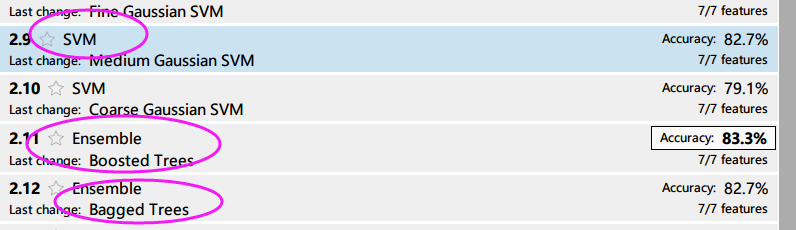

这三个的效果都还不错，我们就导出它们的代码

（1）Medium gaussian svm    中等规模的高斯核支持向量机

rng(111)
trainingData = data;
inputTable = trainingData;
predictorNames = {'Pclass', 'Sex', 'Age', 'SibSp', 'Parch', 'Fare', 'Embarked'};
predictors = inputTable(:, predictorNames);
response = inputTable.Survived;
classificationSVM = fitcsvm(...
    predictors, ...
    response, ...
    'KernelFunction', 'gaussian', ...
    'PolynomialOrder', [], ...
    'KernelScale', 2.6, ...
    'BoxConstraint', 1, ...
    'Standardize', true, ...
    'ClassNames', categorical({'0'; '1'}));
predictorExtractionFcn = @(t) t(:, predictorNames);
svmPredictFcn = @(x) predict(classificationSVM, x);
trainedClassifier.predictFcn = @(x) svmPredictFcn(predictorExtractionFcn(x));
trainedClassifier.RequiredVariables = {'Pclass', 'Sex', 'Age', 'SibSp', 'Parch', 'Fare', 'Embarked'};
trainedClassifier.ClassificationSVM = classificationSVM;
trainedClassifier.About = 'This struct is a trained model exported from Classification Learner R2017a.';
trainedClassifier.HowToPredict = sprintf('To make predictions on a new table, T, use: \n  yfit = c.predictFcn(T) \nreplacing ''c'' with the name of the variable that is this struct, e.g. ''trainedModel''. \n \nThe table, T, must contain the variables returned by: \n  c.RequiredVariables \nVariable formats (e.g. matrix/vector, datatype) must match the original training data. \nAClassNamesditional variables are ignored. \n \nFor more information, see How to predict using an exported model.');
inputTable = trainingData;
% Perform cross-validation
partitionedModel = crossval(trainedClassifier.ClassificationSVM, 'KFold', 5);
% Compute validation predictions
[validationPredictions, validationScores] = kfoldPredict(partitionedModel);

% 计算F1score,绘制ROC曲线，计算AUC值
ClassNames = unique(response); % y中各类的名称
kk = 1;   % 指定正类，kk是正类在ClassNamesd中的位置
posclass = ClassNames(kk); % 正类的名称
group = response;
[x1,y1,~,auc1] = perfcurve(group,validationScores(:,kk),posclass);
auc1

auc1 = 0.8372

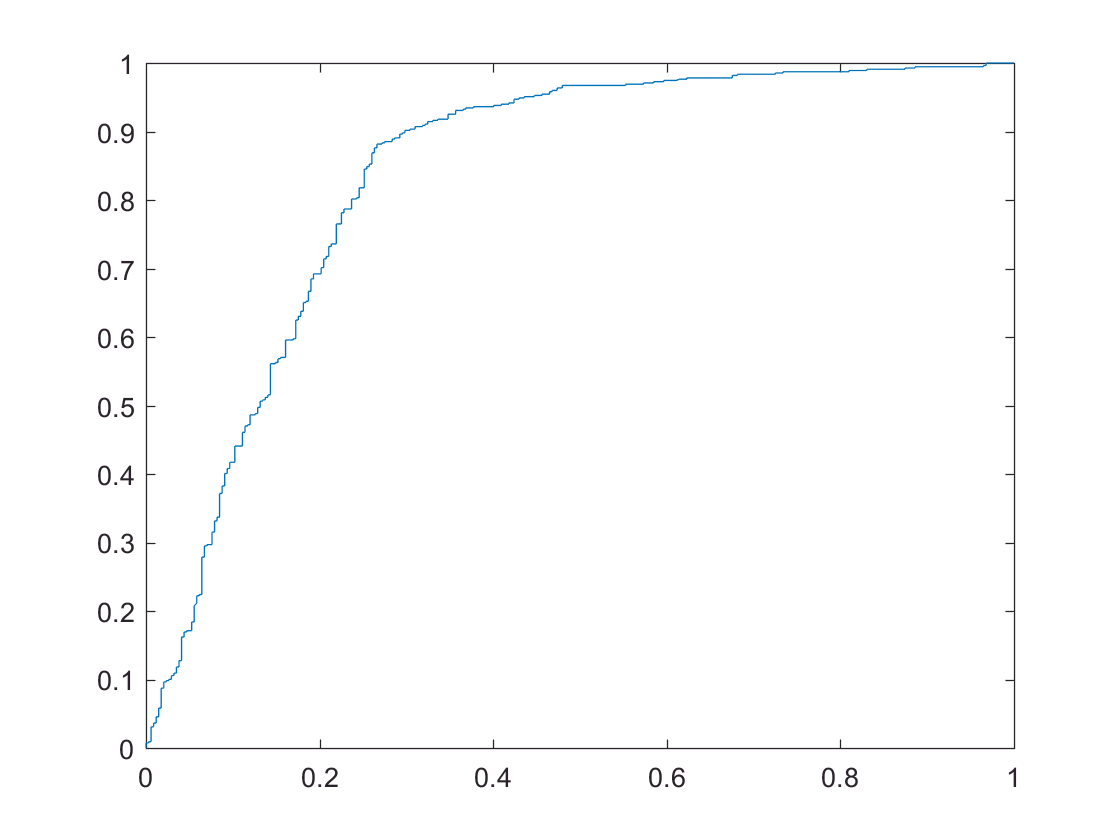

figure(5)
plot(x1,y1)

别忘了把statsOfMeasure.m这个文件放到当前文件夹（进阶课程的第一个视频有介绍）

C = confusionmat(group,validationPredictions,'Order',ClassNames);
stats = statsOfMeasure(C)

stats = 9×4 table
          name               classes          macroAVG    microAVG
    ________________    __________________    ________    ________

    "true_positive"         492        242        367         367 
    "false_positive"        100         57       78.5        78.5 
    "false_negative"         57        100       78.5        78.5 
    "true_negative"         242        492        367         367 
    "precision"         0.83108    0.80936    0.82022     0.82379 
    "sensitivity"       0.89617     0.7076    0.80189     0.82379 
    "specificity"        0.7076    0.89617    0.80189     0.82379 
    "accuracy"          0.82379    0.82379    0.82379     0.82379 
    "F-measure"          0.8624    0.75507    0.80874     0.82379 


F1_score1 = stats.classes(end,kk)  % 二分类用

F1_score1 = 0.8624

（2）Boosted trees  提升树Adaboost

rng(111)
trainingData = data;
inputTable = trainingData;
predictorNames = {'Pclass', 'Sex', 'Age', 'SibSp', 'Parch', 'Fare', 'Embarked'};
predictors = inputTable(:, predictorNames);
response = inputTable.Survived;
template = templateTree(...
    'MaxNumSplits', 20);
classificationEnsemble = fitcensemble(...
    predictors, ...
    response, ...
    'Method', 'AdaBoostM1', ...
    'NumLearningCycles', 30, ...
    'Learners', template, ...
    'LearnRate', 0.1, ...
    'ClassNames', categorical({'0'; '1'}));
predictorExtractionFcn = @(t) t(:, predictorNames);
ensemblePredictFcn = @(x) predict(classificationEnsemble, x);
trainedClassifier.predictFcn = @(x) ensemblePredictFcn(predictorExtractionFcn(x));
trainedClassifier.RequiredVariables = {'Pclass', 'Sex', 'Age', 'SibSp', 'Parch', 'Fare', 'Embarked'};
trainedClassifier.ClassificationEnsemble = classificationEnsemble;
trainedClassifier.About = 'This struct is a trained model exported from Classification Learner R2017a.';
trainedClassifier.HowToPredict = sprintf('To make predictions on a new table, T, use: \n  yfit = c.predictFcn(T) \nreplacing ''c'' with the name of the variable that is this struct, e.g. ''trainedModel''. \n \nThe table, T, must contain the variables returned by: \n  c.RequiredVariables \nVariable formats (e.g. matrix/vector, datatype) must match the original training data. \nAdditional variables are ignored. \n \nFor more information, see How to predict using an exported model.');
partitionedModel = crossval(trainedClassifier.ClassificationEnsemble, 'KFold', 5);
[validationPredictions, validationScores] = kfoldPredict(partitionedModel);

% 计算F1score,绘制ROC曲线，计算AUC值
ClassNames = unique(response); % y中各类的名称
kk = 1;   % 指定正类，kk是正类在ClassNamesd中的位置
posclass = ClassNames(kk); % 正类的名称
group = response;
[x2,y2,~,auc2] = perfcurve(group,validationScores(:,kk),posclass);
auc2

auc2 = 0.8617

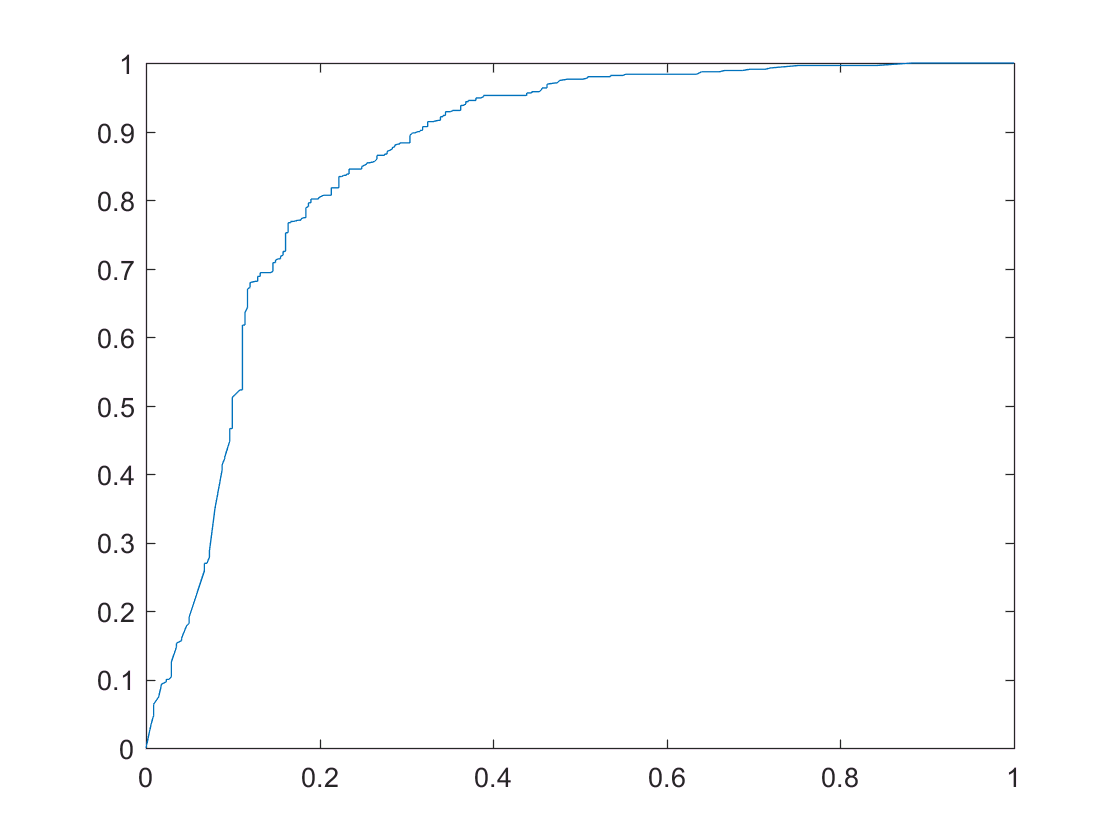

figure(6)
plot(x2,y2)

C = confusionmat(group,validationPredictions,'Order',ClassNames);
stats = statsOfMeasure(C);
F1_score2 = stats.classes(end,kk)  % 二分类用

F1_score2 = 0.8623

（3）Bagged trees  装袋树的升级版：随机森林

rng(111)
trainingData = data;
inputTable = trainingData;
predictorNames = {'Pclass', 'Sex', 'Age', 'SibSp', 'Parch', 'Fare', 'Embarked'};
predictors = inputTable(:, predictorNames);
response = inputTable.Survived;
template = templateTree(...
    'MaxNumSplits', 890);
classificationEnsemble = fitcensemble(...
    predictors, ...
    response, ...
    'Method', 'Bag', ...
    'NumLearningCycles', 30, ...
    'Learners', template, ...
    'ClassNames', categorical({'0'; '1'}));
predictorExtractionFcn = @(t) t(:, predictorNames);
ensemblePredictFcn = @(x) predict(classificationEnsemble, x);
trainedClassifier.predictFcn = @(x) ensemblePredictFcn(predictorExtractionFcn(x));
trainedClassifier.RequiredVariables = {'Pclass', 'Sex', 'Age', 'SibSp', 'Parch', 'Fare', 'Embarked'};
trainedClassifier.ClassificationEnsemble = classificationEnsemble;
trainedClassifier.About = 'This struct is a trained model exported from Classification Learner R2017a.';
trainedClassifier.HowToPredict = sprintf('To make predictions on a new table, T, use: \n  yfit = c.predictFcn(T) \nreplacing ''c'' with the name of the variable that is this struct, e.g. ''trainedModel''. \n \nThe table, T, must contain the variables returned by: \n  c.RequiredVariables \nVariable formats (e.g. matrix/vector, datatype) must match the original training data. \nAdditional variables are ignored. \n \nFor more information, see How to predict using an exported model.');
partitionedModel = crossval(trainedClassifier.ClassificationEnsemble, 'KFold', 5);
[validationPredictions, validationScores] = kfoldPredict(partitionedModel);

% 计算F1score,绘制ROC曲线，计算AUC值
ClassNames = unique(response); % y中各类的名称
kk = 1;   % 指定正类，kk是正类在ClassNamesd中的位置
posclass = ClassNames(kk); % 正类的名称
group = response;
[x3,y3,~,auc3] = perfcurve(group,validationScores(:,kk),posclass);
auc3

auc3 = 0.8666

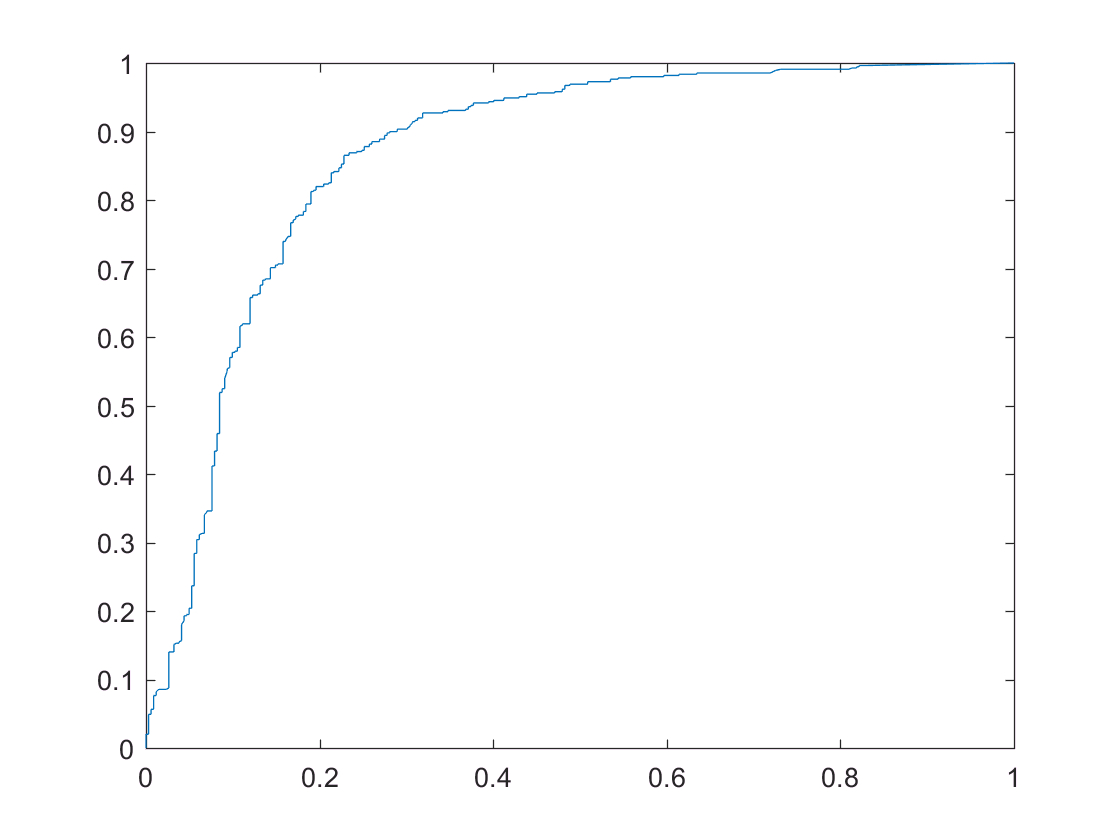

figure(7)
plot(x3,y3)

C = confusionmat(group,validationPredictions,'Order',ClassNames);
stats = statsOfMeasure(C);
F1_score3 = stats.classes(end,kk)  % 二分类用

F1_score3 = 0.8652

三个模型的结果放到一起

auc = [auc1 auc2 auc3]

auc =     0.8372    0.8617    0.8666


F1_score = [F1_score1 F1_score2 F1_score3]

F1_score =     0.8624    0.8623    0.8652


ROC曲线画在同一张图上

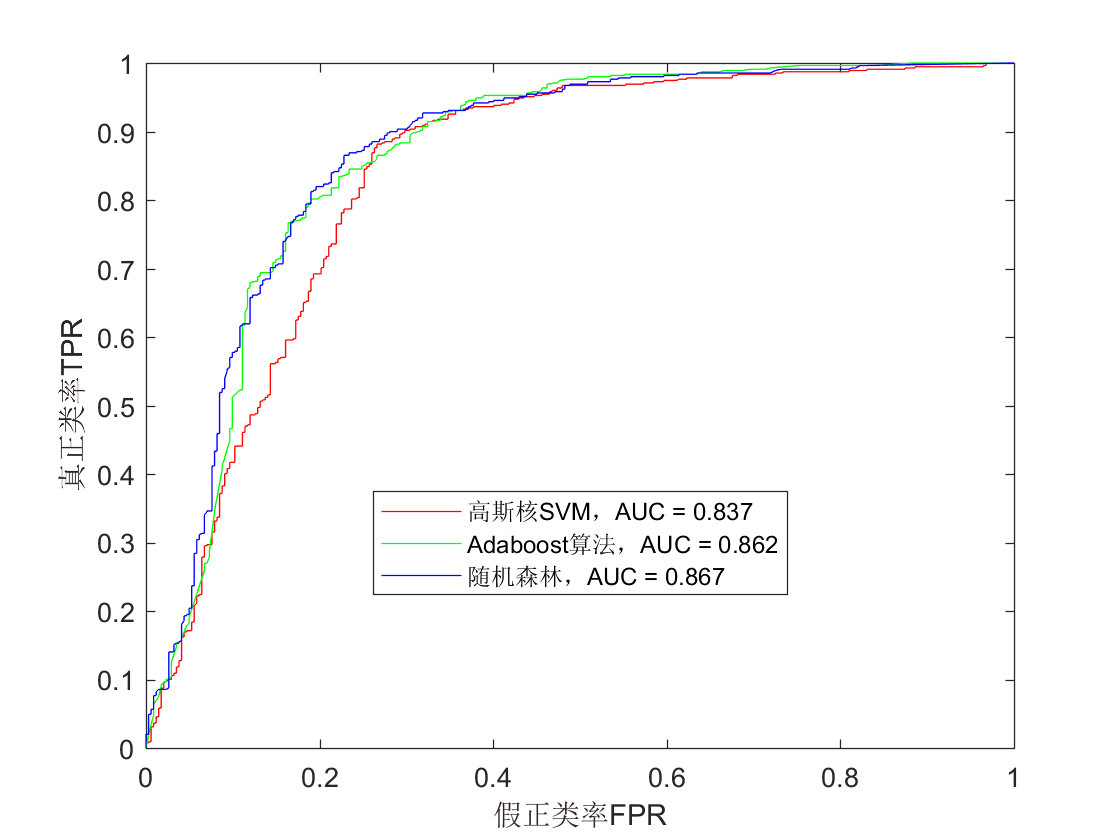

close
figure(8)
plot(x1,y1,'r');
hold on
plot(x2,y2,'g');
plot(x3,y3,'b');
% 使用中括号来拼接字符，字符之间用逗号或者空格隔开
string1 = ['高斯核SVM' , '，AUC = ', num2str(round(auc1,3))];
string2 = ['Adaboost算法', '，AUC = ' , num2str(round(auc2,3))];
string3 = ['随机森林', '，AUC = ' , num2str(round(auc3,3))];
legend(string1,string2,string3,'Location','Best')  % location可以设置放置的位置，best是自动放到最佳的位置
xlabel('假正类率FPR'); ylabel('真正类率TPR');

下面以Bagged trees为例进行网格搜索：

MaxNumSplits : [100 300 500 700 890]  最大分裂的数量 （可以自己根据需求给定，MATLAB默认是样本数减去1）

NumLearningCycles：10:10:200    弱分类器个数，即决策树的个数

本次网格搜索的目标是找到最大的F1_score，你也可以找AUC最大

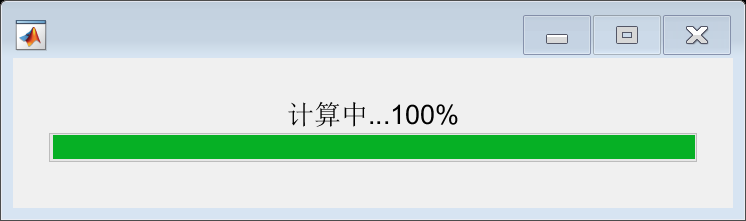

% trainingData = data;
% inputTable = trainingData;
% predictorNames = {'Pclass', 'Sex', 'Age', 'SibSp', 'Parch', 'Fare', 'Embarked'};
% predictors = inputTable(:, predictorNames);
% response = inputTable.Survived;
% MaxNumSplits = [100 300 500 700 890];
% NumLearningCycles = 10:10:200;
% num_i = length(MaxNumSplits);
% num_j = length(NumLearningCycles);
% F1_SCORE = zeros(num_i,num_j);
% mywaitbar = waitbar(0); 
% TOTAL_NUM = num_i*num_j; 
% now_num = 0;
% for i = 1:num_i
%     for j = 1:num_j
%     rng(111)  % 设定随机数种子，保证结果的可重复性(这里的111也可以换成其他的数字)
%     template = templateTree(...
%         'MaxNumSplits', MaxNumSplits(i));
%     classificationEnsemble = fitcensemble(...
%         predictors, ...
%         response, ...
%         'Method', 'Bag', ...
%         'NumLearningCycles', NumLearningCycles(j), ...
%         'Learners', template, ...
%         'ClassNames', categorical({'0'; '1'}));
%         predictorExtractionFcn = @(t) t(:, predictorNames);
%         ensemblePredictFcn = @(x) predict(classificationEnsemble, x);
%         trainedClassifier.predictFcn = @(x) ensemblePredictFcn(predictorExtractionFcn(x));
%         trainedClassifier.RequiredVariables = {'Pclass', 'Sex', 'Age', 'SibSp', 'Parch', 'Fare', 'Embarked'};
%         trainedClassifier.ClassificationEnsemble = classificationEnsemble;
%         trainedClassifier.About = 'This struct is a trained model exported from Classification Learner R2017a.';
%         trainedClassifier.HowToPredict = sprintf('To make predictions on a new table, T, use: \n  yfit = c.predictFcn(T) \nreplacing ''c'' with the name of the variable that is this struct, e.g. ''trainedModel''. \n \nThe table, T, must contain the variables returned by: \n  c.RequiredVariables \nVariable formats (e.g. matrix/vector, datatype) must match the original training data. \nAdditional variables are ignored. \n \nFor more information, see How to predict using an exported model.');
%         partitionedModel = crossval(trainedClassifier.ClassificationEnsemble, 'KFold', 5);
%         [validationPredictions, validationScores] = kfoldPredict(partitionedModel);
%         C = confusionmat(group,validationPredictions,'Order',ClassNames);
%         stats = statsOfMeasure(C);
%         F1_SCORE(i,j) = stats.classes(end,kk);
%         now_num = now_num+1;
%         mystr=['计算中...',num2str(100*now_num/TOTAL_NUM),'%'];   
%         waitbar(now_num/TOTAL_NUM,mywaitbar,mystr);
%     end
% end

% save F1_SCORE.mat F1_SCORE
load  F1_SCORE.mat 

画热力图

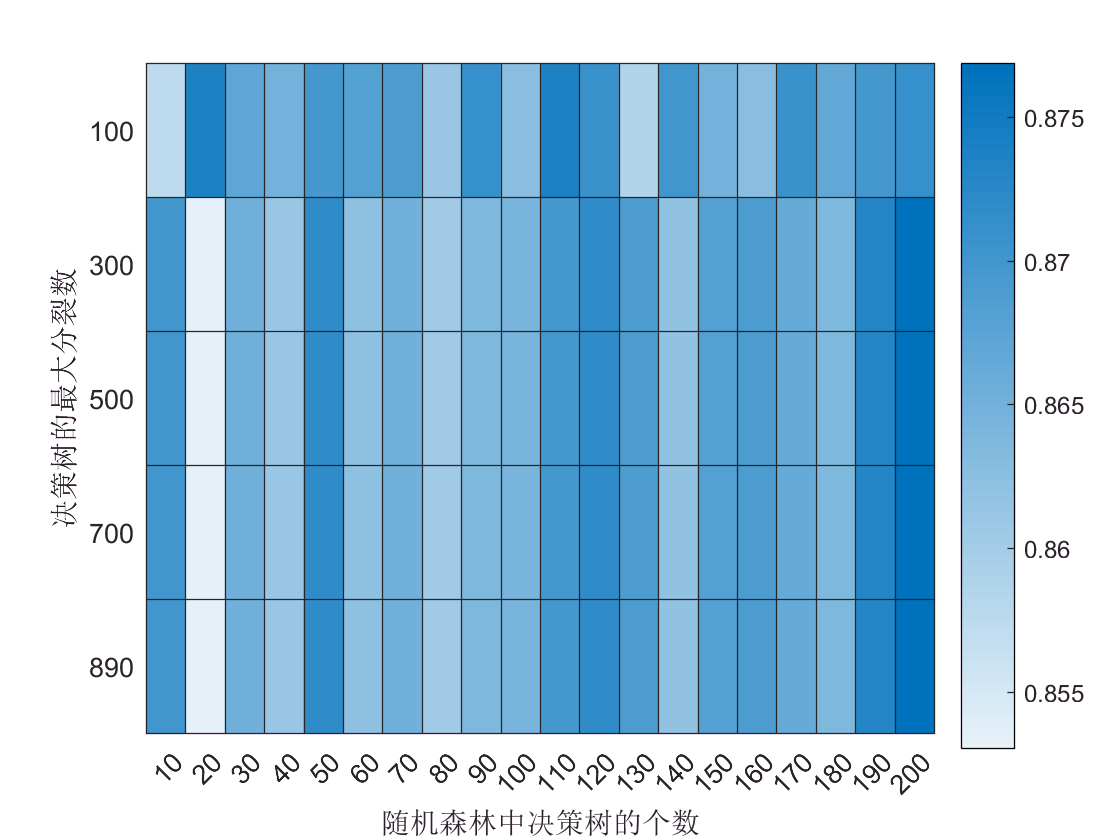

figure(9)
MaxNumSplits = [100 300 500 700 890];
NumLearningCycles = 10:10:200;
h_graph = heatmap(NumLearningCycles,MaxNumSplits,F1_SCORE); 
h_graph.XLabel = '随机森林中决策树的个数';
h_graph.YLabel = '决策树的最大分裂数';

best_f1_score = max(F1_SCORE(:))

best_f1_score = 0.8769

[r,c] = find(F1_SCORE== best_f1_score,1);
best_MaxNumSplits = MaxNumSplits(r)  % 决策树的最大分裂数

best_MaxNumSplits = 300

 best_NumLearningCycles = NumLearningCycles(c) % 随机森林中决策树的个数

best_NumLearningCycles = 200

rng(111)  % 设定随机数种子，保证结果的可重复性
trainingData = data;
inputTable = trainingData;
predictorNames = {'Pclass', 'Sex', 'Age', 'SibSp', 'Parch', 'Fare', 'Embarked'};
predictors = inputTable(:, predictorNames);
response = inputTable.Survived;
 template = templateTree(...
     'MaxNumSplits', best_MaxNumSplits);
 classificationEnsemble = fitcensemble(...
     predictors, ...
     response, ...
     'Method', 'Bag', ...
     'NumLearningCycles', best_NumLearningCycles, ...
     'Learners', template, ...
     'ClassNames', categorical({'0'; '1'}));
 predictorExtractionFcn = @(t) t(:, predictorNames);
 ensemblePredictFcn = @(x) predict(classificationEnsemble, x);
 trainedClassifier.predictFcn = @(x) ensemblePredictFcn(predictorExtractionFcn(x));
 trainedClassifier.RequiredVariables = {'Pclass', 'Sex', 'Age', 'SibSp', 'Parch', 'Fare', 'Embarked'};
 trainedClassifier.ClassificationEnsemble = classificationEnsemble;
 trainedClassifier.About = 'This struct is a trained model exported from Classification Learner R2017a.';
 trainedClassifier.HowToPredict = sprintf('To make predictions on a new table, T, use: \n  yfit = c.predictFcn(T) \nreplacing ''c'' with the name of the variable that is this struct, e.g. ''trainedModel''. \n \nThe table, T, must contain the variables returned by: \n  c.RequiredVariables \nVariable formats (e.g. matrix/vector, datatype) must match the original training data. \nAdditional variables are ignored. \n \nFor more information, see How to predict using an exported model.');
 partitionedModel = crossval(trainedClassifier.ClassificationEnsemble, 'KFold', 5);
 [validationPredictions, validationScores] = kfoldPredict(partitionedModel);
 ClassNames = unique(response); % y中各类的名称
 kk = 1;   % 指定正类，kk是正类在ClassNamesd中的位置
 posclass = ClassNames(kk); % 正类的名称
 group = response;
 C = confusionmat(group,validationPredictions,'Order',ClassNames);
 stats = statsOfMeasure(C);
 f1_score = stats.classes(end,kk)

f1_score = 0.8769

 **我们还可以看看哪个指标对预测的结果最重要**

如果自变量中有分类变量的话，得到的指标重要性的结果可能是有偏的，我们需要更改决策树中的设置

 template = templateTree('PredictorSelection','curvature', ...
                         'MaxNumSplits', best_MaxNumSplits);
 classificationEnsemble = fitcensemble(...
     predictors, ...
     response, ...
     'Method', 'Bag', ...
     'NumLearningCycles', best_NumLearningCycles, ...
     'Learners', template, ...
     'ClassNames', categorical({'0'; '1'}));

因为这里给输入变量加入噪声的过程具有随机性，因此每次可能得到的结果有所不同

oobPermutedPredictorImportance(classificationEnsemble)

ans =     2.2503    5.2720    1.3760    0.7651    0.7215    1.5262    1.1522


为了让结果更加稳健，我们这里可以重复计算Q次，然后取一个平均的结果

(运行一次的速度较慢，这里的Q也别给的太大了，不然计算时间太长)

 Q = 10;
 importance = 0;
 for q = 1:Q
     importance =oobPermutedPredictorImportance(classificationEnsemble)+importance;
 end
 importance = importance / Q;
 % 可以将重要性归一化到[0 1]区间内
 importance(importance<0) = 0;
 importance = importance./sum(importance)

importance =     0.1725    0.4098    0.1011    0.0606    0.0597    0.1145    0.0818


指标较多时，横坐标的标签可能显示的不全，保险起见我们可以加上" *h_bar.Parent.XTick = 1:length(importance); *"   这一行

如果图中右侧留下的空白过多，可以加上" *h_bar.Parent.XLim = [0, length(importance)+1];* "  这一行

还可以调整y轴的范围，这样柱子显得更加自然，可以加上 "  *h_bar.Parent.YLim = [0, max(importance)*1.1]; * "  这一行

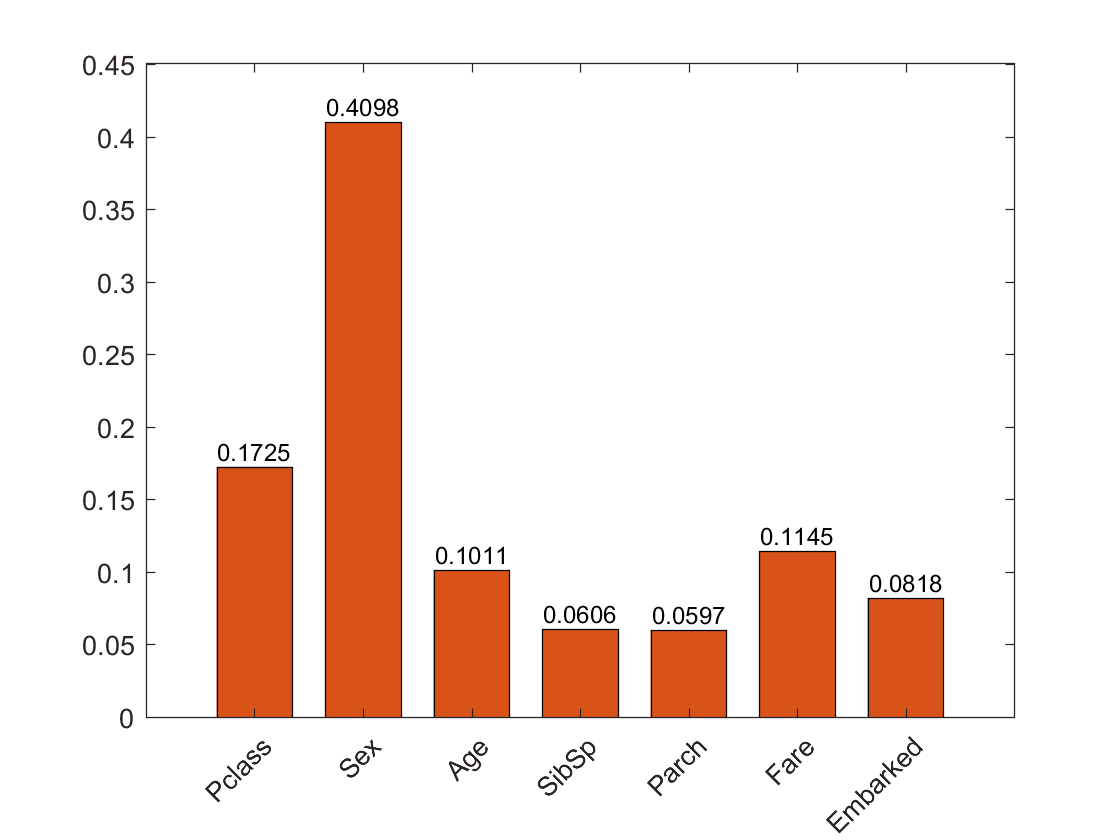

% 画一个柱状图
figure(10)
h_bar = bar(importance);
h_bar.Parent.XTickLabel =predictors.Properties.VariableNames;  
h_bar.Parent.XTickLabelRotation = 45;  
h_bar.Parent.TickLabelInterpreter =  'none';
h_bar.Parent.XTick = 1:length(importance);  
h_bar.Parent.XLim = [0, length(importance)+1];   % 设置x轴的范围
h_bar.Parent.YLim = [0, max(importance)*1.1];  % 设置y轴的范围
% % 提取出大于某个阈值重要性的指标
% threshold = 1/length(importance);  % 阈值默认为:1除以指标个数
% ind = h_bar.Parent.XTickLabel(importance>threshold)
% 怎么在柱子上加上数值?
xtips = h_bar.XData;
ytips = h_bar.YData;
labels = string(round(h_bar.YData,4));  % 保留小数点后四位小数
% 垂直对齐设置为底部对齐 , 水平对齐设置为居中，字体大小设置为9
text(xtips,ytips,cellstr(labels),...
    'VerticalAlignment','bottom',...
    'HorizontalAlignment','center',...
    'FontSize' , 9)
% 还可以更改柱子的属性   https://ww2.mathworks.cn/help/matlab/ref/bar.html
h_bar.BarWidth = 0.7;   % 修改柱子的宽度，默认值是0.8
h_bar.FaceColor = [0.8500 0.3250 0.0980]; % 设置柱子的填充颜色，这里的向量表示RGB三色

导入需要我们预测的数据，进行预测啦！(下面是导入数据工具箱自动生成的脚本)

filename = 'test.csv';
delimiter = ',';
startRow = 2;
formatSpec = '%f%C%q%C%f%f%f%q%f%C%C%[^\n\r]';
fileID = fopen(filename,'r');
dataArray = textscan(fileID, formatSpec, 'Delimiter', delimiter, 'TextType', 'string', 'EmptyValue', NaN, 'HeaderLines' ,startRow-1, 'ReturnOnError', false, 'EndOfLine', '\r\n');
fclose(fileID);
data2 = table(dataArray{1:end-1}, 'VariableNames', {'PassengerId','Pclass','Name','Sex','Age','SibSp','Parch','Ticket','Fare','Cabin','Embarked'});
clearvars filename delimiter startRow formatSpec fileID dataArray ans;

预测之前先对数据进行清理

head(data2,5)  % 查看前五行
missing_num = sum(ismissing(data2)) % 缺失值个数

Age和Fare有缺失值，它们都是连续型变量，我们可以使用均值填充

age = data2.Age;
v = mean(age,'omitnan');  % 平均值
F = fillmissing(age,'constant',v);  % 利用fillmissing函数填补缺失值
data2.Age = F;  % 用F替换表格中的Age

fare = data2.Fare;
v = mean(fare,'omitnan');  % 平均值
F = fillmissing(fare,'constant',v);  % 利用fillmissing函数填补缺失值
data2.Fare = F;  % 用F替换表格中的Fare

调用我们前面的模型进行预测：

[class_hat, score] = trainedClassifier.predictFcn(data2)

**把结果保存到本地，两种方法**

**（1）先把数据弄到表格中，然后使用writetable函数将其保存为csv的文件。**

（我测试过，使用别的函数例如xlswrite保存数据可能会出问题，writetable保存的csv文件可以用excel打开）

my_answer = table(class_hat, score);  % 创建一个表格
writetable(my_answer,'my_answer.csv','Delimiter',',','QuoteStrings',true)
%  将'Delimiter'设置为 ','表示csv文件的每一列的间隔是逗号
%  将'QuoteStrings'设置为true可以排除部分列中也存在英文逗号的干扰
% 注意：如果你的数据中有中文，而且导出的csv中出现了中文乱码，请尝试下面的两行代码
% writetable(my_answer,'my_answer.csv','Delimiter',',','QuoteStrings',true,'Encoding','UTF-8')
% writetable(my_answer,'my_answer.csv','Delimiter',',','QuoteStrings',true,'Encoding','gbk')

**（2）打开工作区的变量，自己手动复制粘贴到excel里面**

**后续的讨论：**

**（1）挖掘更多有用的信息出来**

比如我们没有用到的指标：Name:乘客姓名和Ticket:票号

**（2）缺失值的处理我们可以尝试使用其他方法**